## Operacions aritmètiques

**Valor absolut**: abs(A-B) > llindar

**Rectificat positiu**: A - B > llindar

**Rectificat negatiu**: A -B < llindar

**Re-escalat**: (A-B + 128)

#### Exercici 1

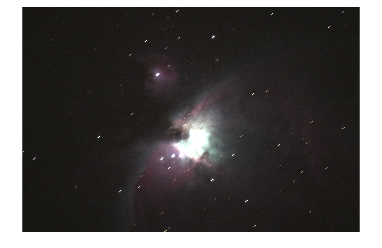

A = double(imread('_MG_7735.jpg'))/255;
B = double(imread("_MG_7737.jpg"))/255;
C = A+B;
imshow(C)

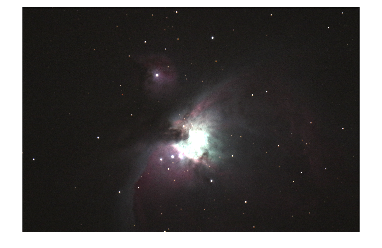



X = [474 3106];
Y = [494 3082];


D = imtranslate(A,(X-Y));
E = D+B;
imshow(E)

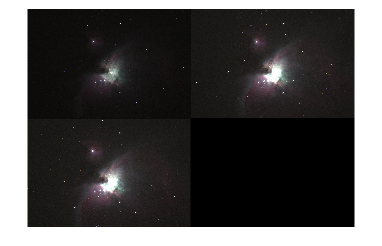

montage({A,C,E})

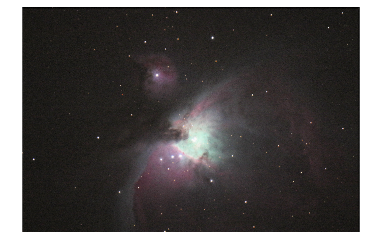


HSV = rgb2hsv(E/2);
V = HSV(:,:,3); % value
V = myfunction3(V);
HSV(:,:,3) = V;
RGB = hsv2rgb(HSV);
imshow(RGB);

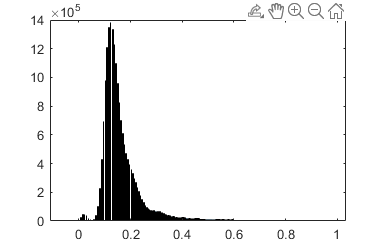

% imcontrast
histogram(V);